# Problem Set III: Information Theory

clc; clear; close all;

## Problem 1

disp('Problem 1')

Problem 1



% Define symbols and respective probabilities
symbols =   {'a',  'b',  'c',  'd',  'e',  'f',  'g',  'h' };
p       =   [0.24, 0.21, 0.18, 0.15, 0.07, 0.06, 0.05, 0.04];

%%% Part (a)

### Part (a)

disp('Part (a)')

Part (a)


% Codeword lengths
l = ceil(-log2(p));

% Kraft sum
kraft_sum = sum(2.^(-l));

disp('Codeword lengths (l):');

Codeword lengths (l):


disp(l);

     3     3     3     3     4     5     5     5




% Show that Kraft inequality is satisfied
disp('Kraft Inequality:');

Kraft Inequality:


disp([num2str(kraft_sum) ' <= 1']);

0.65625 <= 1


if kraft_sum <= 1
    disp('The code lengths satisfy the Kraft inequality.');
else
    disp('The code lengths do not satisfy the Kraft inequality.');
end

The code lengths satisfy the Kraft inequality.


### Part (b)

disp('Part (b)')

Part (b)


% Entropy H(X)
H_X = sum(-p .* log2(p));

% Average code length L_bar
L_bar = sum(p .* l);

disp('Entropy H(X):');

Entropy H(X):


disp(H_X);

    2.7367



disp('Average code length L_bar:');

Average code length L_bar:


disp(L_bar);

    3.3700




% Verify the inequality H(X) <= L_bar < H(X) + 1
disp('H(X) <= L_bar < H(X) + 1')

H(X) <= L_bar < H(X) + 1


disp([num2str(H_X) ' <= ' num2str(L_bar) ' < ' num2str(H_X + 1)]);

2.7367 <= 3.37 < 3.7367


if H_X <= L_bar && L_bar < H_X + 1
    disp('The inequality H(X) <= L_bar < H(X) + 1 is satisfied.');
else
    disp('The inequality H(X) <= L_bar < H(X) + 1 is not satisfied.');
end

The inequality H(X) <= L_bar < H(X) + 1 is satisfied.


## Problem 2

disp('Problem 2')

Problem 2


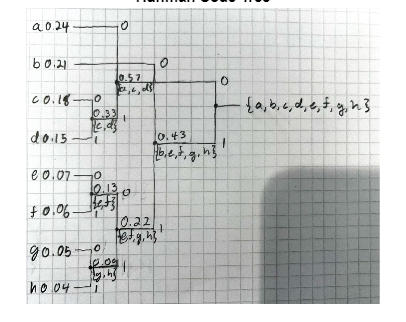


% Code Tree
img = imread('Code Tree.jpeg');
imshow(img);
title('Huffman Code Tree');


% Symbols         a     b     c      d      e       f       g        h
huffman_codes = {'00', '10', '010', '011', '1100', '1101', '1110', '1111'};

% Calculate Huffman code lengths
huffman_lengths = cellfun(@length, huffman_codes);

% Calculate -log2(p) for each probability
neg_log2_p = -log2(p);

% Code Table
code_table = table(symbols', p', huffman_codes', huffman_lengths', round(neg_log2_p, 2)', l', ...
                   'VariableNames', {'Symbol', 'Probability', 'Code', 'Length', '-log2(p)', 'ceil(-log2(p))'});
disp('Huffman Code Table:');

Huffman Code Table:


disp(code_table);

    Symbol    Probability      Code      Length    -log2(p)    ceil(-log2(p))
    ______    ___________    ________    ______    ________    ______________

    {'a'}        0.24        {'00'  }      2         2.06            3       
    {'b'}        0.21        {'10'  }      2         2.25            3       
    {'c'}        0.18        {'010' }      3         2.47            3       
    {'d'}        0.15        {'011' }      3         2.74            3       
    {'e'}        0.07        {'1100'}      4         3.84            4       
    {'f'}        0.06        {'1101'}      4         4.06            5       
    {'g'}        0.05        {'1110'}      4         4.32            5       
    {'h'}        0.04        {'1111'}      4         4.64            5       




% Kraft inequality for Huffman codes
kraft_sum_huffman = sum(2.^(-huffman_lengths));
disp('Kraft inequality (Huffman):');

Kraft inequality (Huffman):


disp([num2str(kraft_sum_huffman) ' <= 1']);

1 <= 1


if kraft_sum_huffman <= 1
    disp('The Huffman code lengths satisfy the Kraft inequality.');
else
    disp('The Huffman code lengths do not satisfy the Kraft inequality.');
end

The Huffman code lengths satisfy the Kraft inequality.



% Average code length L_bar for the Huffman code
L_bar_huffman = sum(p .* huffman_lengths);
disp('Average code length L_bar for Huffman code:');

Average code length L_bar for Huffman code:


disp(L_bar_huffman)

    2.7700




% Verify the inequality H(X) <= L_bar < H(X) + 1
disp('H(X) <= L_bar < H(X) + 1')

H(X) <= L_bar < H(X) + 1


disp([num2str(H_X) ' <= ' num2str(L_bar_huffman) ' < ' num2str(H_X + 1)]);

2.7367 <= 2.77 < 3.7367


if H_X <= L_bar_huffman && L_bar_huffman < H_X + 1
    disp('The inequality H(X) <= L_bar < H(X) + 1 is satisfied for the Huffman code.');
else
    disp('The inequality H(X) <= L_bar < H(X) + 1 is not satisfied for the Huffman code.');
end

The inequality H(X) <= L_bar < H(X) + 1 is satisfied for the Huffman code.


## Problem 3

disp('Problem 3')

Problem 3


### Part (a)

disp('Part (a)')

Part (a)



three_binit_sequences = {'000',     '001',     '010', '011', '100',     '101',     '110', '111'};
three_binit_probs     = [0.24*0.57, 0.24*0.43, 0.18,  0.15,  0.21*0.57, 0.21*0.43, 0.13,  0.09];
% sum_three_binit_probs = sum(three_binit_probs); % Check the sum of
% probabilities is 1

disp('3-Binit Sequence Probabilities:')

3-Binit Sequence Probabilities:


results_table = table(three_binit_sequences', round(three_binit_probs, 2)', ...
                      'VariableNames', {'3_Binit_Sequence', 'Probability'});
disp(results_table);

    3_Binit_Sequence    Probability
    ________________    ___________

        {'000'}            0.14    
        {'001'}             0.1    
        {'010'}            0.18    
        {'011'}            0.15    
        {'100'}            0.12    
        {'101'}            0.09    
        {'110'}            0.13    
        {'111'}            0.09    



### Part (b)

disp('Part (b)')

Part (b)



%% Entropy H(Y3)
% Marginal probabilities for Y3 (0 or 1)
p_Y3_0 = sum(three_binit_probs([1, 3, 5, 7])); % Sequences where Y3 = 0
p_Y3_1 = sum(three_binit_probs([2, 4, 6, 8])); % Sequences where Y3 = 1

H_Y3 = (-p_Y3_0 * log2(p_Y3_0) - p_Y3_1 * log2(p_Y3_1));
disp('Entropy H(Y3):')

Entropy H(Y3):


disp(H_Y3)

    0.9872




%% Entropy H(Y3 | Y2)
% Marginal probabilities for Y2 (0 or 1)
p_Y2_0 = sum(three_binit_probs([1, 2, 7, 8])); % Sequences where Y2 = 0
p_Y2_1 = sum(three_binit_probs([3, 4, 5, 6])); % Sequences where Y2 = 1

% Conditional probabilities for Y3 given Y2
p_Y3_0_given_Y2_0 = sum(three_binit_probs([1, 7])) / p_Y2_0;
p_Y3_1_given_Y2_0 = sum(three_binit_probs([2, 8])) / p_Y2_0;
p_Y3_0_given_Y2_1 = sum(three_binit_probs([3, 5])) / p_Y2_1;
p_Y3_1_given_Y2_1 = sum(three_binit_probs([4, 6])) / p_Y2_1;

H_Y3_given_Y2 = p_Y2_0 * (-p_Y3_0_given_Y2_0 * log2(p_Y3_0_given_Y2_0) - p_Y3_1_given_Y2_0 * log2(p_Y3_1_given_Y2_0)) ...
              + p_Y2_1 * (-p_Y3_0_given_Y2_1 * log2(p_Y3_0_given_Y2_1) - p_Y3_1_given_Y2_1 * log2(p_Y3_1_given_Y2_1));
disp('Conditional Entropy H(Y3 | Y2):')

Conditional Entropy H(Y3 | Y2):


disp(H_Y3_given_Y2)

    0.9867




%% Entropy H(Y3 | Y1, Y2)
% Joint probabilities of each (Y1, Y2) pair
p_Y1Y2_00 = sum(three_binit_probs([1, 2])); % (Y1, Y2) = (0, 0)
p_Y1Y2_01 = sum(three_binit_probs([3, 4])); % (Y1, Y2) = (0, 1)
p_Y1Y2_10 = sum(three_binit_probs([5, 6])); % (Y1, Y2) = (1, 0)
p_Y1Y2_11 = sum(three_binit_probs([7, 8])); % (Y1, Y2) = (1, 1)

% Conditional probabilities for Y3 given each (Y1, Y2) combination
% (Y1, Y2) = (0, 0)
p_Y3_0_given_Y1Y2_00 = three_binit_probs(1) / p_Y1Y2_00;
p_Y3_1_given_Y1Y2_00 = three_binit_probs(2) / p_Y1Y2_00;

% (Y1, Y2) = (0, 1)
p_Y3_0_given_Y1Y2_01 = three_binit_probs(3) / p_Y1Y2_01;
p_Y3_1_given_Y1Y2_01 = three_binit_probs(4) / p_Y1Y2_01;

% (Y1, Y2) = (1, 0)
p_Y3_0_given_Y1Y2_10 = three_binit_probs(5) / p_Y1Y2_10;
p_Y3_1_given_Y1Y2_10 = three_binit_probs(6) / p_Y1Y2_10;

% (Y1, Y2) = (1, 1)
p_Y3_0_given_Y1Y2_11 = three_binit_probs(7) / p_Y1Y2_11;
p_Y3_1_given_Y1Y2_11 = three_binit_probs(8) / p_Y1Y2_11;

% Combine the conditional entropies weighted by the probability of each (Y1, Y2) pair
H_Y3_given_Y1Y2 = p_Y1Y2_00 * (-p_Y3_0_given_Y1Y2_00 * log2(p_Y3_0_given_Y1Y2_00) - ...
                                p_Y3_1_given_Y1Y2_00 * log2(p_Y3_1_given_Y1Y2_00)) + ...
                  p_Y1Y2_01 * (-p_Y3_0_given_Y1Y2_01 * log2(p_Y3_0_given_Y1Y2_01) - ...
                                p_Y3_1_given_Y1Y2_01 * log2(p_Y3_1_given_Y1Y2_01)) + ...
                  p_Y1Y2_10 * (-p_Y3_0_given_Y1Y2_10 * log2(p_Y3_0_given_Y1Y2_10) - ...
                                p_Y3_1_given_Y1Y2_10 * log2(p_Y3_1_given_Y1Y2_10)) + ...
                  p_Y1Y2_11 * (-p_Y3_0_given_Y1Y2_11 * log2(p_Y3_0_given_Y1Y2_11) - ...
                                p_Y3_1_given_Y1Y2_11 * log2(p_Y3_1_given_Y1Y2_11));
disp('Conditional Entropy H(Y3 | Y1, Y2):')

Conditional Entropy H(Y3 | Y1, Y2):


disp(H_Y3_given_Y1Y2)

    0.9864



### Part (c)

disp('Part (c)')

Part (c)


disp('H(Y3) > H(Y3 | Y2) > H(Y3 | Y1, Y2)')

H(Y3) > H(Y3 | Y2) > H(Y3 | Y1, Y2)


disp(num2str(H_Y3) + " > " + num2str(H_Y3_given_Y2) + " > " + num2str(H_Y3_given_Y1Y2))

0.9872 > 0.98675 > 0.98637


if H_Y3 >= H_Y3_given_Y2 && H_Y3_given_Y2 >= H_Y3_given_Y1Y2
    disp('This is a decreasing sequence');
else
    disp('This is not a decreasing sequence');
end

This is a decreasing sequence


## Problem 4

disp('Problem 4')

Problem 4


### Part (a)

 
$$p_{y_0} = P(Y = 0) = \pi_0 (1 - p) + (1 - \pi_0) \cdot 2p$$


### Part (b)


$$I(X, Y) = \sum_{x_i} \sum_{y_j} p(x_i, y_j) \ln \frac{p(x_i, y_j)}{\pi_{x_i} p(y_j)}$$



$$I(X, Y) = p(0, 0) \ln \frac{p(0, 0)}{\pi_0 p(y_0)} + p(0, 1) \ln \frac{p(0, 1)}{\pi_0 p(y_1)} + p(1, 0) \ln \frac{p(1, 0)}{(1 - \pi_0) p(y_0)} + p(1, 1) \ln \frac{p(1, 1)}{(1 - \pi_0) p(y_1)}$$


Using the given error probabilities


$$P(Y = 0 | X = 0) = 1 - p$$



$$P(Y = 1 | X = 0) = p$$



$$P(Y = 0 | X = 1) = 2p$$



$$P(Y = 1 | X = 1) = 1 - 2p$$


The joint probabilities are


$$p(0, 0) = P(X = 0) \cdot P(Y = 0 | X = 0) = \pi_0 (1 - p)$$



$$p(0, 1) = P(X = 0) \cdot P(Y = 1 | X = 0) = \pi_0 \cdot p$$



$$p(1, 0) = P(X = 1) \cdot P(Y = 0 | X = 1) = (1 - \pi_0) \cdot 2p$$



$$p(1, 1) = P(X = 1) \cdot P(Y = 1 | X = 1) = (1 - \pi_0) \cdot (1 - 2p)$$


The marginal probabilities of $Y$ are


$$p(y_0) = P(Y = 0) = p_{y_0} = \pi_0 (1 - p) + (1 - \pi_0) \cdot 2p$$



$$p(y_1) = P(Y = 1) = 1 - p_{y_0} = \pi_0 \cdot p + (1 - \pi_0) \cdot (1 - 2p)$$


Substituting into $I(X,Y)$


$$I(X, Y) = \pi_0 (1 - p) \ln \frac{\pi_0 (1 - p)}{\pi_0 \cdot (\pi_0 (1 - p) + (1 - \pi_0) \cdot 2p)}$$



$$+ \pi_0 \cdot p \ln \frac{\pi_0 \cdot p}{\pi_0 \cdot (\pi_0 \cdot p + (1 - \pi_0) \cdot (1 - 2p))}$$



$$+ (1 - \pi_0) \cdot 2p \ln \frac{(1 - \pi_0) \cdot 2p}{(1 - \pi_0) \cdot (\pi_0 (1 - p) + (1 - \pi_0) \cdot 2p)}$$



$$+ (1 - \pi_0) \cdot (1 - 2p) \ln \frac{(1 - \pi_0) \cdot (1 - 2p)}{(1 - \pi_0) \cdot (\pi_0 \cdot p + (1 - \pi_0) \cdot (1 - 2p))}$$


Expands into


$$I(X, Y) = \pi_0 (1 - p) \left( \ln \pi_0 + \ln (1 - p) - \ln (\pi_0 (1 - p) + (1 - \pi_0) \cdot 2p) \right)$$



$$+ \pi_0 \cdot p \left( \ln \pi_0 + \ln p - \ln (\pi_0 \cdot p + (1 - \pi_0) \cdot (1 - 2p)) \right)$$



$$+ (1 - \pi_0) \cdot 2p \left( \ln (1 - \pi_0) + \ln 2p - \ln (\pi_0 (1 - p) + (1 - \pi_0) \cdot 2p) \right)$$



$$+ (1 - \pi_0) \cdot (1 - 2p) \left( \ln (1 - \pi_0) + \ln (1 - 2p) - \ln (\pi_0 \cdot p + (1 - \pi_0) \cdot (1 - 2p)) \right)$$


Further


$$I(X, Y) = -[\pi_0 (1 - p) + (1 - \pi_0) \cdot 2p] \ln [\pi_0 (1 - p) + (1 - \pi_0) \cdot 2p]$$



$$- (1 - [\pi_0 (1 - p) + (1 - \pi_0) \cdot 2p]) \ln (1 - [\pi_0 (1 - p) + (1 - \pi_0) \cdot 2p])$$



$$+ \pi_0 \cdot [p \ln p + (1 - p) \ln (1 - p)]$$



$$+ (1 - \pi_0) \cdot [2p \ln (2p) + (1 - 2p) \ln (1 - 2p)]$$


Thus, using the binary entropy function $\varphi(p) = -p \ln p - (1 - p) \ln (1 - p)$. We can express $I(X, Y)$ as


$$I(X, Y) = \varphi(a) + b \varphi(p) + c \varphi(2p)$$


where


$$a = p_{y_0} = \pi_0 (1 - p) + (1 - \pi_0) \cdot 2p$$



$$b = -\pi_0$$



$$c = -(1 - \pi_0)$$


### Part (c)


$$\varphi'(p) = -\ln p - 1 + \ln (1 - p) + 1 = \ln \frac{1 - p}{p}$$


### Part (d)

`To find the channel capacity, we maximize the mutual information `$I(X, Y)$` with respect to the input distribution `$\pi_0$`. `

`Thus we want to set `$\partial I / \partial \pi_0 = 0$`.`

### `Part (e)`


$$\frac{\partial I}{\partial \pi_0} = 0$$



$$\frac{\partial I}{\partial \pi_0} = \frac{\partial \varphi(p_{y_0})}{\partial p_{y_0}} \cdot \frac{\partial p_{y_0}}{\partial \pi_0} - \varphi(p) + \varphi(2p) = 0$$


`where`


$$\frac{\partial \varphi(p_{y_0})}{\partial p_{y_0}} = \varphi'(p_{y_0})$$



$$\frac{\partial p_{y_0}}{\partial \pi_0} = 1 - 3p$$


`Thus, the equation becomes`


$$\varphi'(p_{y_0}) (1 - 3p) - \varphi(p) + \varphi(2p) = 0$$


`which expands into`


$$\ln\frac{1 - (\pi_0 (1 - 3p) + 2p)}{(\pi_0 (1 - 3p) + 2p)} (1 - 3p)$$



$$- [-p \ln p - (1 - p) \ln(1 - p)]$$



$$+ [-2p \ln(2p) - (1 - 2p) \ln(1 - 2p)] = 0$$


### Part (f)

disp('Part (f)')

Part (f)


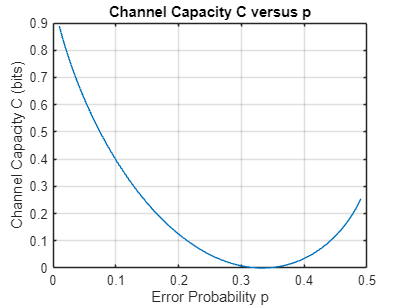

num_points = 250;
p_values = linspace(0.01, 0.49, num_points); % Avoid endpoints to prevent log(0)

% Preallocate arrays for results
C_values = zeros(1, num_points);
pi_0_optimal = zeros(1, num_points);

% Binary entropy function
phi = @(x) -x .* log(x) - (1 - x) .* log(1 - x);

% Loop over each value of p
for i = 1:num_points
    p = p_values(i);
    
    % Define the equation for optimal pi_0 as a function to be solved
    equation = @(pi_0) ...
        log((1 - (pi_0 * (1 - 3 * p) + 2 * p)) / (pi_0 * (1 - 3 * p) + 2 * p)) * (1 - 3 * p) ...
        - ( -p * log(p) - (1 - p) * log(1 - p) ) ...
        + ( -2 * p * log(2 * p) - (1 - 2 * p) * log(1 - 2 * p) );
    
    % Initial guess for fsolve
    pi_0_guess = 0.5;
    
    % Solve for optimal pi_0
    pi_0_opt = fsolve(equation, pi_0_guess, optimset('Display','off'));
    pi_0_optimal(i) = pi_0_opt;
    
    % Calculate p(y_0) based on optimal pi_0
    p_y0 = pi_0_opt * (1 - p) + (1 - pi_0_opt) * 2 * p;
    
    % Compute mutual information at the optimal pi_0
    C_values(i) = phi(p_y0) ...
        - pi_0_opt * phi(p) ...
        - (1 - pi_0_opt) * phi(2 * p);
    
    % Convert from nats to bits
    C_values(i) = C_values(i) / log(2);
end

% Plot channel capacity C versus p
figure;
plot(p_values, C_values);
title('Channel Capacity C versus p');
xlabel('Error Probability p');
ylabel('Channel Capacity C (bits)');
grid on;

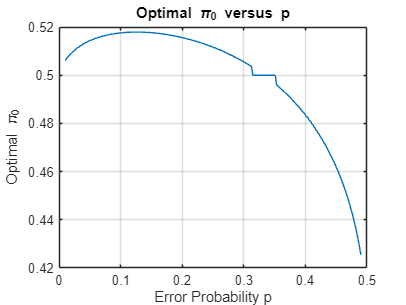


% Plot optimal pi_0 versus p
figure;
plot(p_values, pi_0_optimal);
title('Optimal \pi_0 versus p');
xlabel('Error Probability p');
ylabel('Optimal \pi_0');
grid on;

## Problem 5

% Given variances
sigma_squared = [1, 0.8, 0.1, 0.01];

% Desired target rate range
target_R_min = 4.9;
target_R_max = 5;

% Initial values for bisection
lambda_low = 0;
lambda_high = max(sigma_squared);
max_iterations = 10;

% Pre-allocate arrays
iteration_list = zeros(max_iterations, 1);
lambda_low_list = zeros(max_iterations, 1);
lambda_high_list = zeros(max_iterations, 1);
lambda_list = zeros(max_iterations, 1);
R_list = zeros(max_iterations, 1);
D_list = zeros(max_iterations, 1);

% Initialize variables to store optimal values
optimal_lambda = 0;
final_R = 0;
final_D = 0;

for iteration = 1:max_iterations
    lambda = (lambda_low + lambda_high) / 2;
    R = 0;
    D = 0;
    
    % Calculate R and D based on current lambda
    for i = 1:length(sigma_squared)
        if sigma_squared(i) > lambda
            % Component contributes to rate and distortion
            D_i = lambda;
            R_i = 0.5 * log2(sigma_squared(i) / lambda);
        else
            % Component does not contribute to rate
            D_i = sigma_squared(i);
            R_i = 0;
        end
        R = R + R_i;
        D = D + D_i;
    end
    
    iteration_list(iteration) = iteration;
    lambda_low_list(iteration) = lambda_low;
    lambda_high_list(iteration) = lambda_high;
    lambda_list(iteration) = lambda;
    R_list(iteration) = R;
    D_list(iteration) = D;
    
    if R > target_R_max
        % R is too high, increase lambda
        lambda_low = lambda;
    elseif R < target_R_min
        % R is too low, decrease lambda
        lambda_high = lambda;
    else
        % R is within target range; save values and break the loop
        optimal_lambda = lambda;
        final_R = R;
        final_D = D;
        break;
    end
end

% Shrink arrays
iteration_list = iteration_list(1:iteration);
lambda_low_list = lambda_low_list(1:iteration);
lambda_high_list = lambda_high_list(1:iteration);
lambda_list = lambda_list(1:iteration);
R_list = R_list(1:iteration);
D_list = D_list(1:iteration);

% Display each iteration in a table
T = table(iteration_list, lambda_low_list, lambda_high_list, lambda_list, R_list, D_list, ...
          'VariableNames', {'Iteration', 'Lambda_Low', 'Lambda_High', 'Lambda', 'R', 'D'});
disp(T);

    Iteration    Lambda_Low    Lambda_High     Lambda        R          D   
    _________    __________    ___________    ________    _______    _______

        1                0             1           0.5    0.83904       1.11
        2                0           0.5          0.25      1.839       0.61
        3                0          0.25         0.125      2.839       0.36
        4                0         0.125        0.0625     4.1781     0.1975
        5                0        0.0625       0.03125     5.6781    0.10375
        6          0.03125        0.0625      0.046875     4.8006    0.15063
        7          0.03125      0.046875      0.039062     5.1952    0.12719
        8         0.039062      0.046875      0.042969     4.9889    0.13891




% Display the final result
fprintf('Optimal lambda: %.4f\n', optimal_lambda);

Optimal lambda: 0.0430


fprintf('Final (R, D) point: (%.4f, %.4f)\n', final_R, final_D);

Final (R, D) point: (4.9889, 0.1389)


fprintf('Total iterations: %d\n', iteration);

Total iterations: 8


## Problem 6

`Shannon formula:`


$$C = B \log_2\left(1 + \frac{P}{N_0 B}\right)$$



$$\frac{C}{B} = \log_2\left(1 + \frac{P}{N_0 B}\right)$$



$$2^{\frac{C}{B}} = 1 + \frac{P}{N_0 B}$$



$$\frac{P}{N_0 B} = 2^{\frac{C}{B}} - 1$$



$$P = N_0 B \left(2^{\frac{C}{B}} - 1\right)$$


Thus,


$$C = 1 \times 10^6 \, \text{bps}$$



$$B = 1 \times 10^6 \, \text{Hz}$$



$$N_0 = 10^{-8} \, \text{W/Hz}$$



$$P = (10^{-8} \cdot 1 \times 10^6) \left(2^{\frac{1 \times 10^6}{1 \times 10^6}} - 1\right)$$



$$P = 0.01 \, \text{W} = 10 \, \text{mW}$$
